clear all
clc

# Q3

w =0.05

w = 0.0500

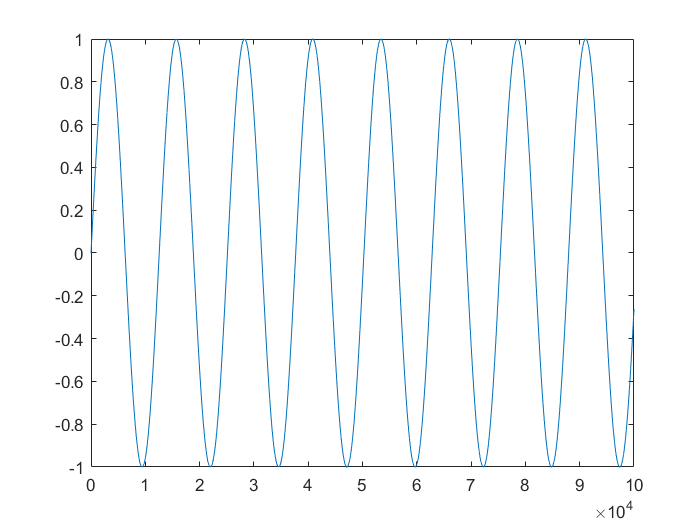

t = linspace(0,1000,100000);
u = sin(w*t);
y = sys(u,t);
plot(u)

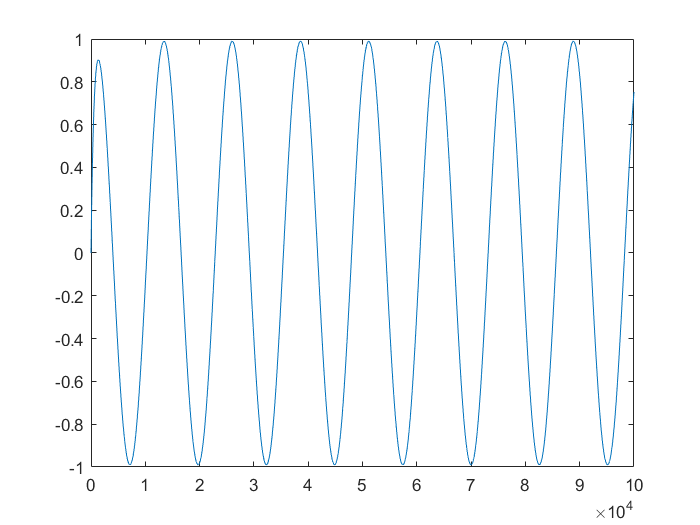

plot(y)

t = linspace(0, 2000, 10000000);
w = logspace(-3, 4, 400); % Frequencies in rad/s
a = 1

a = 1

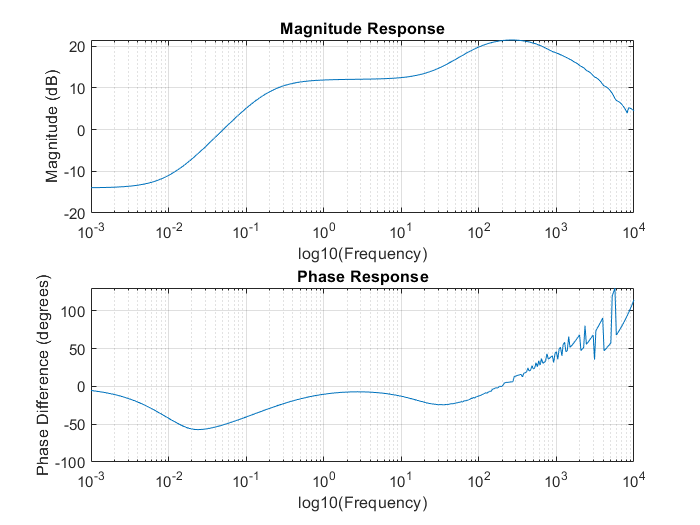

% Preallocate arrays for amplitudes and phase differences
amplitudes = zeros(size(w));
phase_differences = zeros(size(w));

for i = 1:length(w)
    u =a* sin(w(i) * t);
    y = sys(u, t);

    % amplitudes caculating
    amplitudes(i) = 20 * log10(max(y)/max(u));
     
    % phase_differences caculating
    [peak1, peak_ind1] = findpeaks(u);
    [peak2, peakind2] = findpeaks(y);
    phase_differences(i) = (t(peakind2(1)) - t(peak_ind1(1))) * w(i) * 180 / pi;
end

% Plotting the magnitude and phase differences
figure;
subplot(2, 1, 1);
semilogx(w, amplitudes);
xlabel('log10(Frequency)');
ylabel('Magnitude (dB)');
title('Magnitude Response');
grid on
subplot(2, 1, 2);
semilogx(w, phase_differences);
xlabel('log10(Frequency)');
ylabel('Phase Difference (degrees)');
title('Phase Response');
grid on

figure

s = tf('s');
k = 10^(-14/20);
G = k*(1-s/0.005)*(1+s/25)/((1-s/0.1)*(1-s/300)^2)

G =
 
        1796 s^2 + 4.488e04 s - 224.5
  -----------------------------------------
  0.125 s^3 - 75.01 s^2 + 1.126e04 s - 1125
 
Continuous-time transfer function.



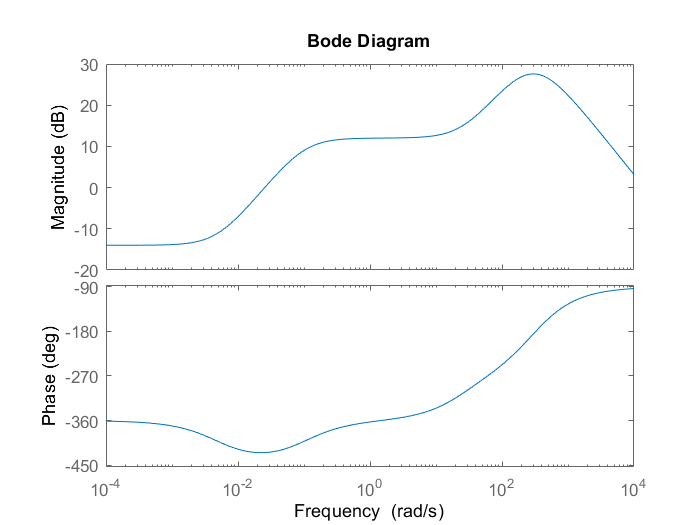

bode(G)